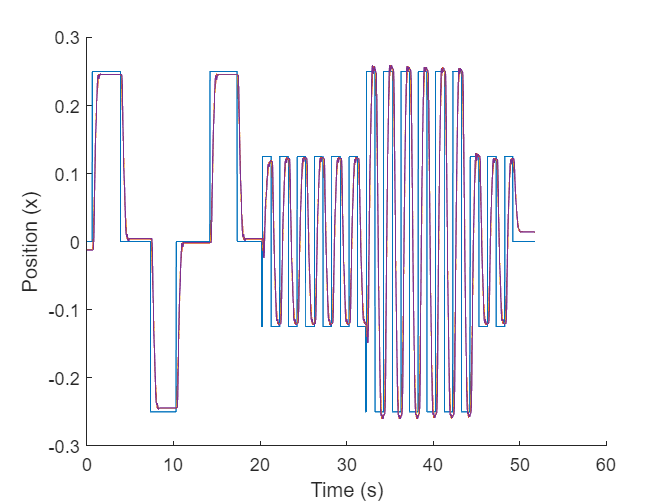

clear, clc;

load('mcg56pp2.mat');
data = mcg56lqr1;

time_array = data.X(1).Data;

C1P = data.Y(1).Data;
C1P_GAIN = data.Y(2).Data;
C1V = data.Y(3).Data;
C1V_GAIN = data.Y(4).Data;

C2P = data.Y(5).Data;
C2P_GAIN = data.Y(6).Data;
C2V = data.Y(7).Data;
C2V_GAIN = data.Y(8).Data;

C3P = data.Y(9).Data;
C3P_GAIN = data.Y(10).Data;
C3V = data.Y(11).Data;
C3V_GAIN = data.Y(12).Data;

CMV = data.Y(13).Data;
PC = data.Y(14).Data;
RMV = data.Y(15).Data; 

% Plot response
figure();
hold on
plot(time_array, PC)
plot(time_array, C1P)
plot(time_array, C2P)
plot(time_array, C3P)
xlabel("Time (s)")
ylabel("Position (x)")

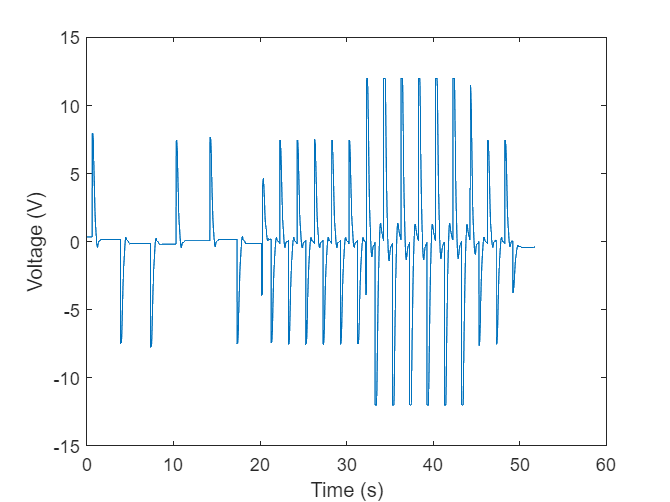

% legend("Cart position", "Input r")


% Plot Voltage
figure();
plot(time_array, RMV)
xlabel("Time (s)")
ylabel("Voltage (V)")



% Print gains - mode takes the most common value
fprintf("Cart 1 position gain: %d", mode(C1P_GAIN));

Cart 1 position gain: 2.360000e+01

fprintf("Cart 2 position gain: %d", mode(C2P_GAIN));

Cart 2 position gain: 1.030000e+01

fprintf("Cart 3 position gain: %d", mode(C3P_GAIN));

Cart 3 position gain: -3.500000e+00